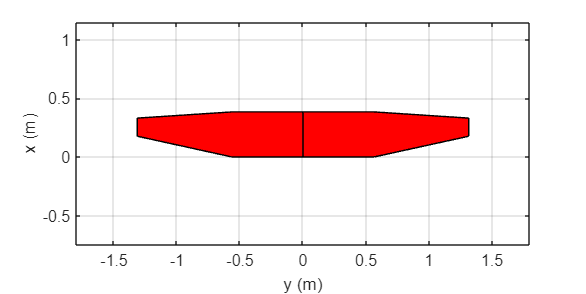

bf = [0.3840 0.4024 2.6281 0.4287 0.0528];

% SALVA UM PLOT COM O MELHOR RESULTADO:
x = [0 0 (bf(3)/2)*bf(4) (bf(3)/2)...
    (bf(3)/2) (bf(3)/2)*bf(4)];
y = [0 bf(1) bf(1) (bf(1)-...
    bf(5)) (bf(1)-bf(5)-...
    (bf(1)*bf(2))) 0];

figure;
set(figure, 'Units', 'centimeters', 'Position', [5, 5, 20, 10]); % 20 cm de largura e 10 cm de altura
fill(x, y, 'r', -x, y, 'r')
axis([-1.8 1.8 -0.75 1.15])
xlabel('y (m)')
ylabel('x (m)')
grid on;

set(gcf, 'PaperOrientation', 'landscape'); % Define a orientação como paisagem
set(gcf, 'PaperPositionMode', 'auto'); % Ajusta o gráfico na folha
print('Fig28','-dpng','-r450')

valores = [11.093
11.868
11.868
11.868
11.868
11.954
11.954
11.954
11.954
11.954
11.954
11.954
11.954
11.954
11.954
11.954
11.954
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.023
12.072
12.072
12.187
12.187
12.187
12.187
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.212
12.235
12.235
12.235
12.235
12.235
12.235
12.235
12.235
12.235
12.235
12.256]

valores =    11.0930
   11.8680
   11.8680
   11.8680
   11.8680
   11.9540
   11.9540
   11.9540
   11.9540
   11.9540


lista = 1:100

lista =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


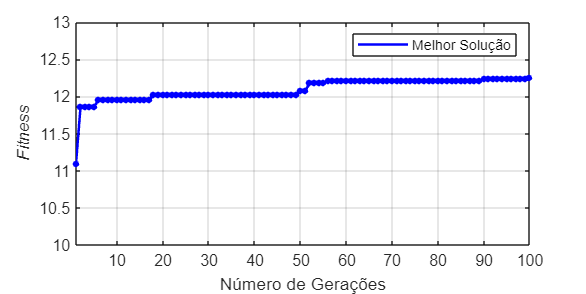


figure;
set(figure, 'Units', 'centimeters', 'Position', [5, 5, 20, 10]); % 20 cm de largura e 10 cm de altura

plot(lista, valores', 'LineWidth',1.5, 'Color', 'blue');
hold on
scatter(lista, valores', 15, 'blue', 'filled');

xlabel('Número de Gerações');
ylabel('\itFitness\rm');
legend('Melhor Solução', 'Location', 'northeast')
axis([1 100 10 13]);
grid on;
set(gcf, 'PaperOrientation', 'landscape'); % Define a orientação como paisagem
set(gcf, 'PaperPositionMode', 'auto'); % Ajusta o gráfico na folha
print('Grande','-dpng','-r450')

    INPUT.design.chord_r = individual(1);
    INPUT.design.taper = individual(2);
    INPUT.design.span = individual(3);
    INPUT.design.y_taper = individual(4);
    INPUT.design.offset_tip = individual(5);

    % CÁLCULO PARA A TORÇÃO INTERMEDIÁRIA:
    twist_mid = [0.0 -1.0 -2.0 -3.0];
    n = find(individual(6) <= [0.25 0.50 0.75 1.00], 1, 'first');
    INPUT.design.twist_mid = twist_mid(n);

    % CÁLCULO PARA A TORÇÃO NA PONTA:
    twist_tip = [twist_mid(n) twist_mid(n)-1 twist_mid(n)-2 twist_mid(n)-3];
    n = find(individual(7) <= [0.25 0.50 0.75 1.00], 1, 'first');
    INPUT.design.twist_tip = twist_tip(n);

    % CÁLCULO PARA AEROFÓLIO:
    airfoil = ["E423.dat" "UruA84212.dat" "UruA94113.dat" "UruA104612.dat"];
    n = find(individual(8) <= [0.25 0.50 0.75 1.0], 1, 'first');
    INPUT.design.airfoil = airfoil(n);

    % CÁLCULO PARA O GRUPO MOTOPROPULSOR:
    GMP = [[-0.0249 -1.2568 102.3320]
              [-0.0273 -0.07934 115.8218]
              [-0.0282 -0.2911 122.6452]
              [-0.0332 -2.3898 116.6083]
              [-0.0284 -1.5923 125.6174]
              [-0.0311 -1.0840 143.4866]
              [-0.0330 -0.4877 154.1342]];
    n = find(individual(9) <= [0.143 0.286 0.429 0.572 0.715 0.858 1.000], 1, 'first');
    INPUT.design.power_plant = GMP(n,:);


[OUTPUT] = AVL_RUN (INPUT);

Sref = 0.836;

g = INPUT.world.gravity;
rho = INPUT.world.density;
mu = INPUT.world.friction;
Ta = INPUT.design.power_plant(1);
Tb = INPUT.design.power_plant(2);
Tc = INPUT.design.power_plant(3);
CD0 = INPUT.decisions.friction_drag;
h_o = INPUT.decisions.obstacle;

CL = OUTPUT.AVL.CL;
CDi = OUTPUT.AVL.CDi;

INPUT.world.gravity = 9.81;  %(m/s²)
INPUT.world.density = 1.108; %(kg/m³)
INPUT.world.friction = 0.04;
INPUT.decisions.TO_dist = 55; %(m)
INPUT.decisions.obstacle = 0.8; %(m)
INPUT.decisions.friction_drag = 0.016;
INPUT.decisions.wing_density = 1.5;


% DEFINIÇÃO DAS VARIÁVEIS IMPORTANTES PARA O LOOP: 
v_x = 0; a_x = 0;                              % Velocidade-X em t=0.
vx_list = zeros(1,10); t_list = zeros(1,10);   % Listas de Armazenamento.
i = 1;                                         % Contador de Iterações.


% DEFINIÇÕES DA FORÇA PESO E DA SUSTENTAÇÃO:
W = m * g;                                     % Peso para determinado m.
L = 0;                                         % Sustentação em t=0.


% SIMULAÇÃO DA CORRIDA EM SOLO:
for t = 0 : 0.05 : 30
    if L <= W
        v0_x = v_x;                            % Velocidade-X em t-1.
        v_x = v0_x + a_x * 0.05;               % Velocidade-X em t.

        q = 0.5 * rho * (v_x)^2;               % Pressão dinâmica em t.
        T = (Ta * (v_x)^2) + (Tb * v_x) + Tc;  % Tração em t.
        D = q * Sref * (CD0 + CDi);            % Arrasto em t.
        L = q * Sref * CL;                     % Sustentação em t.
        R = mu * (W - L);                      % Atrito em t.

        a_x = (T - D - R)/m;                   % Aceleração-X em t.

        vx_list(i) = v_x;                      % Armezenamento de V_x.
        t_list(i) = t;                         % Armezenamento de t.
        i = i + 1;                           
    end
end


% CÁLULO DA DISTÂNCIA PERCORRIDA NA CORRIDA EM SOLO:
s_g = trapz(t_list(1:end), vx_list(1:end));


% TRANSIÇÃO ATÉ ULTRAPASSAR O OBSTÁCULO:
tr_r = 0.2156 * ((1.045*v_x)^2);                % Raio de transição.
s_t = sqrt(tr_r^2 - (tr_r-h_o)^2);             % Distância - ultrapassagem.

s_tot = s_g + s_t;                             % Distância total.